# Linear Control Design II - Group Work Problem Module 6

## Description

This exercise is based on the work carried out in the Group Work Problem Module 2. For the electro-mechanical system illustrated in Figure 1 and described in Group Work Problem Module 2 the goals for this assignment is: a) linearize the electromagnetic force resulted from the change in current and change in displacement. I.e. $Ki$ and $Ks$; b) derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


c)  investigate the vibrations of the structure when different initial conditions and inputs are present;

d) compare the obtained results from Group Work Module 2 with the results from this Group Work Module.

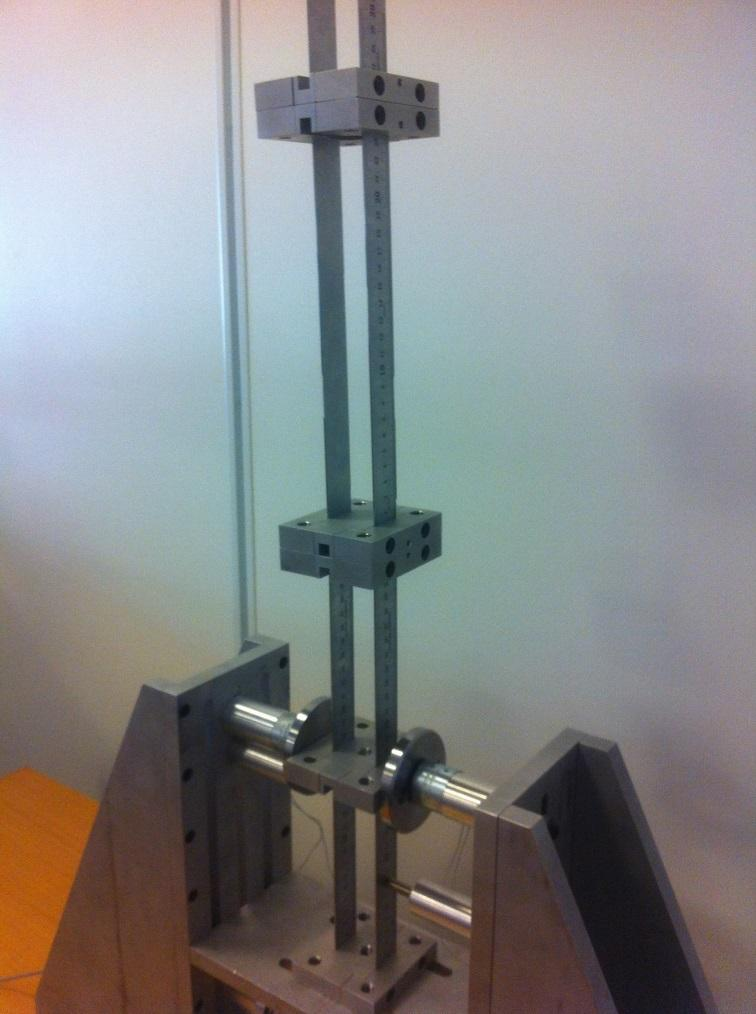


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


The parameters needed for the assignment are given below.

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

l = 24e-3; % mm, small
r = 14e-3 / 2; % radius of magnet
A = pi*r^2; % area of the magnet
R = 148.2; % resistance
L = 800e-3; % [H] % inductance of the magnet
iMax = 0.14; % measured at 24v

gam = 0.5;          % bias ratio - normally chosen between 0.2-0.5
ib = iMax*gam;      % Bias current
mu = 4*pi*1e-7;     % Permeability of free space (vacuum)
x0 = 2e-3;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

**Problem 1**

Linearize the electromagnetic force resulted from the change in current and change in displacement.

Define $Ki$ and $Ks$


$$K_i=\frac{\mu_0N^2A_ai_0}{{x_0}^2}$$



$$K_s =\frac{\mu_0N^2A_a{i_0}^2}{{x_0}^3}$$


% Your solution goes here
% Ki
syms mu N A ib x0
Ki = mu*N*N*A*ib/power(x0,2)

$$Ki = \frac{A\,N^{2}\,\mathrm{ib}\,\mu }{{x_{0}}^{2}}$$

% Ks
Ks = mu*N*N*A*ib*ib/power(x0,3)

$$Ks = \frac{A\,N^{2}\,{\mathrm{ib}}^{2}\,\mu }{{x_{0}}^{3}}$$

**Problem 2**

Derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


% Your solution goes here:
% Upload a picture or fill in your code 
syms R L K_i K_s m1 m2 m3 k1 k2 k3

Ax = [
        -R/L        0         -K_i/L       0         0    0   0
          0         0             1       0         0    0   0
       K_i/m1 -(k1+k2+K_s)/m1    0     k2/m1       0    0   0
          0         0             0       0         1    0   0
          0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
          0         0             0       0         0    0   1
          0         0             0     k3/m3       0 -k3/m3 0 ]

$$Ax = \left(\begin{array}{ccccccc} -\frac{R}{L} & 0 & -\frac{K_{i}}{L} & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0\\ \frac{K_{i}}{m_{1}} & -\frac{K_{s}+k_{1}+k_{2}}{m_{1}} & 0 & \frac{k_{2}}{m_{1}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & \frac{k_{2}}{m_{2}} & 0 & -\frac{k_{2}+k_{3}}{m_{2}} & 0 & \frac{k_{3}}{m_{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & \frac{k_{3}}{m_{3}} & 0 & -\frac{k_{3}}{m_{3}} & 0 \end{array}\right)$$

Bx = [1/L 0 0 0 0 0 0]'

$$Bx = \left(\begin{array}{c} \frac{1}{\bar{L}}\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Cx = [0 1 0 0 0 0 0]

Cx =      0     1     0     0     0     0     0


Dx = 0;

**Problem 3**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results. 

**Solution:**

% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

l = 24e-3; % mm, small
r = 14e-3 / 2; % radius of magnet
A = pi*r^2; % area of the magnet
R = 148.2; % resistance
L = 800e-3; % [H] % inductance of the magnet
iMax = 0.14; % measured at 24v

gam = 0.5;          % bias ratio - normally chosen between 0.2-0.5
ib = iMax*gam;      % Bias current
mu = 4*pi*1e-7;     % Permeability of free space (vacuum)
x0 = 5e-3;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular

b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

K_i = mu*N*N*A*ib/power(x0,2)/2; % no idea why /2 to meet the answer
K_s = -mu*N*N*A*ib*ib/power(x0,3)/4;% no idea why /4 to be the same as answer


x_0 = [0 0.001 0 0 0 0 0]'; 
Ax = eval(subs(Ax))

Ax = 	1.0e+04 *

   -0.0185         0   -0.0014         0         0         0         0
         0         0    0.0001         0         0         0         0
    0.0016   -1.0334         0    0.5837         0         0         0
         0         0         0         0    0.0001         0         0
         0    0.9711         0   -1.1656         0    0.1946         0
         0         0         0         0         0         0    0.0001
         0         0         0    0.1946         0   -0.1946         0


Bx = eval(subs(Bx))

Bx =     1.2500
         0
         0
         0
         0
         0
         0


Cx = eval(subs(Cx))

Cx =      0     1     0     0     0     0     0


Dx = eval(subs(Dx))

Dx = 0

% Ax = [
%         -R/L        0         -Ki/L       0         0    0   0
%           0         0             1       0         0    0   0
%        -Ki/m1 -(k1+k2+Ks)/m1    0     k2/m1       0    0   0
%           0         0             0       0         1    0   0
%           0       k2/m2           0  -(k2 + k3)/m2  0  k3/m2 0
%           0         0             0       0         0    0   1
%           0         0             0     k3/m3       0 -k3/m3 0 ]
% Bx = [1/L 0 0 0 0 0 0]'
% Cx = [0 1 0 0 0 0 0 0]
% Dx = 0


**Similarities Transformation**

[M, lambda] = eig(Ax)

M =    0.9976 + 0.0000i   0.0281 - 0.0205i   0.0281 + 0.0205i   0.0390 - 0.0139i   0.0390 + 0.0139i  -0.0180 + 0.0034i  -0.0180 - 0.0034i
   0.0004 + 0.0000i  -0.0000 + 0.0042i  -0.0000 - 0.0042i   0.0001 + 0.0090i   0.0001 - 0.0090i  -0.0001 - 0.0074i  -0.0001 + 0.0074i
  -0.0672 + 0.0000i  -0.5723 - 0.0040i  -0.5723 + 0.0040i  -0.5795 + 0.0035i  -0.5795 - 0.0035i   0.2456 - 0.0020i   0.2456 + 0.0020i
   0.0001 + 0.0000i  -0.0000 - 0.0059i  -0.0000 + 0.0059i   0.0000 + 0.0095i   0.0000 - 0.0095i  -0.0001 - 0.0118i  -0.0001 + 0.0118i
  -0.0143 + 0.0000i   0.8138 + 0.0000i   0.8138 + 0.0000i  -0.6135 + 0.0000i  -0.6135 + 0.0000i   0.3891 - 0.0017i   0.3891 + 0.0017i
   0.0000 + 0.0000i   0.0000 + 0.0007i   0.0000 - 0.0007i  -0.0001 - 0.0083i  -0.0001 + 0.0083i  -0.0000 - 0.0268i  -0.0000 + 0.0268i
  -0.0008 + 0.0000i  -0.0944 + 0.0003i  -0.0944 - 0.0003i   0.5345 - 0.0075i   0.5345 + 0.0075i   0.8871 + 0.0000i   0.8871 + 0.0000i


lambda = 	1.0e+02 *

  -1.8431 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0017 + 1.3679i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0017 - 1.3679i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0024 + 0.6464i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0024 - 0.6464i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0006 + 0.3305i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0006 - 0.3305i


P = inv(M)

P =    1.0056 - 0.0000i   2.9716 - 0.0000i   0.0603 - 0.0000i  -1.4242 - 0.0000i   0.0077 - 0.0000i  -0.0772 - 0.0000i   0.0004 + 0.0000i
  -0.0216 + 0.0159i  -0.1727 -53.3912i  -0.3919 - 0.0004i   0.2107 +45.8238i   0.3350 - 0.0020i  -0.0394 - 5.3176i  -0.0389 + 0.0003i
  -0.0216 - 0.0159i  -0.1727 +53.3912i  -0.3919 + 0.0004i   0.2107 -45.8238i   0.3350 + 0.0020i  -0.0394 + 5.3176i  -0.0389 - 0.0003i
  -0.0301 + 0.0102i  -0.0943 -25.4392i  -0.3958 - 0.0036i   0.3061 -16.2780i  -0.2518 - 0.0038i  -0.0671 +14.1846i   0.2194 + 0.0002i
  -0.0301 - 0.0102i  -0.0943 +25.4392i  -0.3958 + 0.0036i   0.3061 +16.2780i  -0.2518 + 0.0038i  -0.0671 -14.1846i   0.2194 - 0.0002i
   0.0162 - 0.0029i   0.2394 + 6.4619i   0.1968 - 0.0007i  -0.0109 + 6.1940i   0.1874 + 0.0000i  -0.0857 +14.1201i   0.4273 + 0.0019i
   0.0162 + 0.0029i   0.2394 - 6.4619i   0.1968 + 0.0007i  -0.0109 - 6.1940i   0.1874 - 0.0000i  -0.0857 -14.1201i   0.4273 - 0.0019i


Bt = P*Bx

Bt =    1.2570 - 0.0000i
  -0.0270 + 0.0199i
  -0.0270 - 0.0199i
  -0.0376 + 0.0128i
  -0.0376 - 0.0128i
   0.0202 - 0.0037i
   0.0202 + 0.0037i


Ct = Cx*inv(P)

Ct =    0.0004 - 0.0000i  -0.0000 + 0.0042i  -0.0000 - 0.0042i   0.0001 + 0.0090i   0.0001 - 0.0090i  -0.0001 - 0.0074i  -0.0001 + 0.0074i


Time constant

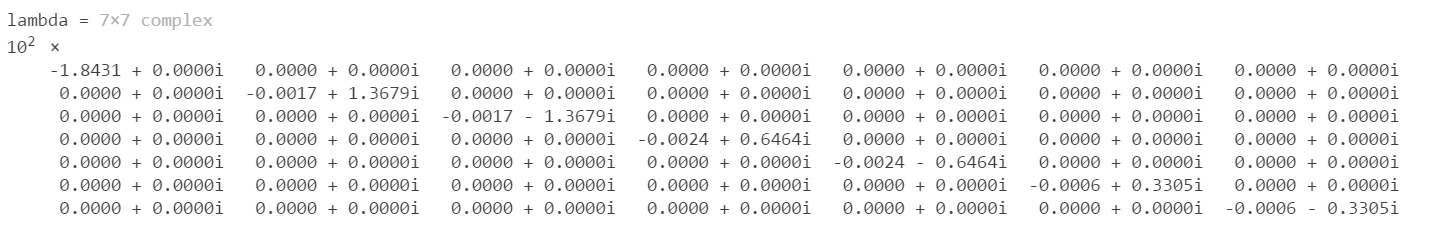

Real pole is 10e2*-1.8431

pi = 10^2*-1.8431

pi = -184.3100

tou= 1/abs(pi)

tou = 0.0054

And damping ratios are left out...